defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure - Phys Temperature']);

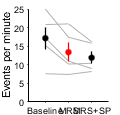

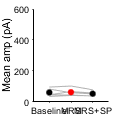

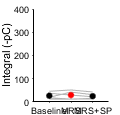

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];
conditions = {'WT'};

%%dir 
dname = '.\Data\WT_*_PT';
temp = dir(dname);
folderList = struct([]);
for i = 1:size(temp,1)
    tempfolds = dir([temp(i).folder '\' temp(i).name])
    folderList = [folderList; tempfolds(3:end)]
end

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

analyze = [1 1 1 1];
for i = 1:size(folderList,1)
        
    if analyze(1)
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_p.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).preR = calcRm(d,time,pulse,pulseTime);
        else
            cellS(i).preR = NaN;
        end
    end

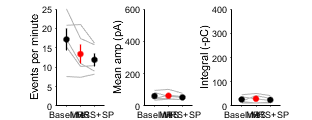

    
    if analyze(2)

        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_gfi.abf']);
        if ~isempty(fileList)
            [d,time,SR] = loadPclampData(fileList{1});
            out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
            cellS(i).Vm = mean(d - out);
        else
            cellS(i).Vm = NaN;
        end
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_gfv.abf']);
        saveList = fileList;
        if ~isempty(fileList)
            [d,time,SR] = loadPclampData(fileList{1});
            out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
            out = lowpass(out,5,5000);
            %figure for assessing basleine
            % figure; plot(time,out);
    %         hold on;
    %         plot(time,d-out);
            [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
            %uncomment for peaks graph
            %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
            cellS(i).rawLocPk = [locs pks];

tempfolds = 13×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


folderList = 11×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Dot indexing is not supported for variables of this type.

            
            if exist('stats')
                clear 'stats'; 
            end
            for j = 1:size(conditionTimes,1)
                if conditionTimes(j,2) < time(end)
                    stats(j).condition = conditions{j};
                    stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                    stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                    cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                             out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
                    stats(j).integral = cumFunc(end);
                else
                    stats(j).condition = conditions{j};
                    stats(j).numPeaks = NaN;
                    stats(j).meanAmp = NaN;
                    stats(j).integral = NaN;
                end
                
            end
            
            cellS(i).stats = stats;
        else
            cellS(i).rawLocPk = NaN;
            cellS(i).stats = NaN;
        end

    end
   
    if analyze(4)
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).postR= calcRm(d,time,pulse,pulseTime);
        else
            cellS(i).postR= NaN;
        end
    end
    if ~isempty(saveList)
        tempCell = cellS(i);
        [d,f,ext] = fileparts(saveList{1});
        save([d '\' f '_WTstats.mat'],'tempCell');
    end
end


for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
    rinstatBlock(i,:) = cellS(i).bl_R;
    vmstatBlock(i,:) = cellS(i).Vm;
end

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];
conditions = {'P2ry1KO'};

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
temp = dir(dname);
folderlist = temp(3:end);
dname = '.\Data\KO_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
dname = '.\Data\KO_BBE_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
folderList = folderlist;

analyze = [1 1 1 1];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

analyze = [1 1 1 1]
for i = 1:size(folderList,1)
        
    if analyze(1)
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_p.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).preR = calcRm(d,time,pulse,pulseTime);
        else
            cellS(i).preR = NaN;
        end
    end
    
    if analyze(2)
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_gfi.abf']);
        if ~isempty(fileList)
            [d,time,SR] = loadPclampData(fileList{1});
            out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
            cellS(i).Vm = mean(d - out);
        else
            cellS(i).Vm = NaN;
        end
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_gfv.abf']);
        saveList = fileList;
        if ~isempty(fileList)
            [d,time,SR] = loadPclampData(fileList{1});
            out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
            out = lowpass(out,5,5000);
            %figure for assessing basleine
            % figure; plot(time,out);
    %         hold on;
    %         plot(time,d-out);
            [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
            %uncomment for peaks graph
            %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
            cellS(i).rawLocPk = [locs pks];
            
            if exist('stats')
                clear 'stats'; 
            end
            for j = 1:size(conditionTimes,1)
                if conditionTimes(j,2) < time(end)
                    stats(j).condition = conditions{j};
                    stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                    stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
                    cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                             out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
                    stats(j).integral = cumFunc(end);
                else
                    stats(j).condition = conditions{j};
                    stats(j).numPeaks = NaN;
                    stats(j).meanAmp = NaN;
                    stats(j).integral = NaN;
                end
                
            end
            
            cellS(i).stats = stats;
        else
            cellS(i).rawLocPk = NaN;
            cellS(i).stats = NaN;
        end

    end
   
    if analyze(4)
        fileList = loadFileList([folderList(i).folder '\' folderList(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).postR= calcRm(d,time,pulse,pulseTime);
        else
            cellS(i).postR= NaN;
        end
    end
    if ~isempty(saveList)
        tempCell = cellS(i);
        [d,f,ext] = fileparts(saveList{1});
        save([d '\' f '_KOstats.mat'],'tempCell');
    end
end


fileList = loadFileList(['.\Data\*\*\*_gfv_WTstats.mat']);

for i=1:size(fileList,1)
    s = load(fileList{i});
    cellS(i)= s.tempCell;
end

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
    vmstatBlock(i,:) = cellS(i).Vm;
end

clear cellS;
fileList = loadFileList(['.\Data\*\*\*_gfv_KOstats.mat']);

for i=1:size(fileList,1)
    s = load(fileList{i});
    cellS(i)= s.tempCell;
end

 
for i = 1:size(cellS,2)
     KOpkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
     KOampstatBlock(i,:) = [cellS(i).stats.meanAmp];
     KOintstatBlock(i,:) = [cellS(i).stats.integral]/300;
     KOvmstatBlock(i,:) = cellS(i).Vm;
end

conditions = {'WT','P2ry1 KO'}; dim = [0.75 1.5]; mkSize = [5 12]; plwidth = '25000000';
h = compare2C(pkstatBlock,KOpkstatBlock,conditions,'Events Per Minute',dim,mkSize);
ylim([0 25]);
yticks(0:5:25);
xtickangle(45);
%export_fig('.\EPS Panels\I_1.eps');

h1 = compare2C(ampstatBlock,KOampstatBlock,conditions,'Mean Amp (pA)',dim,mkSize);
ylim([0 600]);
yticks(0:200:600);
xtickangle(45);
%export_fig('.\EPS Panels\I_2.eps');

h2 = compare2C(intstatBlock,KOintstatBlock,conditions,'Charge Transfer (–pA*s)',dim,mkSize);
ylim([0 400]);
yticks(0:100:400);
xtickangle(45);
%export_fig('.\EPS Panels\I_3.eps');

print('.\EPS Panels\testingIs.pdf','-dpdf')

handleTheSubplot({h,h1,h2},[1,3])
figQuality(gcf,gca,[3 2]);

compare2C(vmstatBlock,KOvmstatBlock,conditions,'Vm',dim,mkSize);
ylim([-105 -75]);



dim = [2 1];
%%example traces for KO and WT animals (chosen as closest to average values)
fileKO = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827018_gfv.abf';
[d,time] = loadPclampData(fileKO);
out = msbackadj(time,-d,'WINDOWSIZE',10,'STEPSIZE',10);
d = -out;
figure;
plot(time,d);
xlim([0 150]);
ylim([-1000 50]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\P2ry1KO_ISC_examplePT.eps')

fileWT = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - ISCs\Data\WT_Furosemide_PT\180907_Cell1\18907003_gfv.abf';
[d,time] = loadPclampData(fileWT);
out = msbackadj(time,-d,'WINDOWSIZE',10,'STEPSIZE',10);
d = -out;
figure;
plot(time,d);
xlim([150 300]);
ylim([-1000 50])
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\P2ry1WT_ISC_examplePT.eps')

%% KO versus LacZ

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];
conditions = {'KO'};

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
temp = dir(dname);
folderlist = temp(3:end);
dname = '.\Data\KO_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
dname = '.\Data\KO_BBE_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];

analyze = [1 1 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;

    end
   
    if analyze(4)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end


for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
    rinstatBlock(i,:) = cellS(i).bl_R;
    vmstatBlock(i,:) = cellS(i).Vm;
end

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];

%%dir 
dname = '.\Data\LacZ_KO_PT';
temp = dir(dname);
folderlist = temp(3:end);
analyze = [1 1 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;

    end
   
    if analyze(4)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end




for i = 1:size(cellS,2)
    KOpkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    KOampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    KOintstatBlock(i,:) = [cellS(i).stats.integral]/300;
    KOrinstatBlock(i,:) = cellS(i).bl_R;
    KOvmstatBlock(i,:) = cellS(i).Vm;
end

conditions = {'KO','LacZ KO'};
dim = [1.5 2];
compare2C(pkstatBlock,KOpkstatBlock,conditions,'Events Per Minute',dim);
ylim([0 25]);
yticks(0:5:25);
figQuality(gcf,gca,[1.5 2]);
export_fig('.\EPS Panels\KO_LacZ\freq.eps')

  compare2C(ampstatBlock,KOampstatBlock,conditions,'Mean Amp (pA)',dim);
ylim([0 150]);
yticks(0:50:150);
export_fig('.\EPS Panels\KO_LacZ\amp.eps')

compare2C(intstatBlock,KOintstatBlock,conditions,'Charge Transfer (-pA*s)',dim);
ylim([0 200]);
yticks(0:50:200);
export_fig('.\EPS Panels\KO_LacZ\int.eps')

compare2C(rinstatBlock,KOrinstatBlock,conditions,'Input Resistance (MOhm)',dim);
ylim([0 75]);
yticks(0:25:75);
export_fig('.\EPS Panels\KO_LacZ\Rin.eps')

compare2C(vmstatBlock,KOvmstatBlock,conditions,'Vm',dim);
ylim([-100 -85]);
yticks(-100:5:-85);
export_fig('.\EPS Panels\KO_LacZ\Vm.eps')

%plot all cells

dname = '.\Data\KO_MRS_PPADS_PT';
temp = dir(dname);
folderlist = temp(3:end);
dname = '.\Data\KO_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
dname = '.\Data\KO_BBE_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
outHold = [];
outHold2 = [];
%figure;
count = 0;
for i = 7
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % plot(time,-out + (i-1)*500); hold on;
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        if size(out(time >= 0 & time <= 300),1) <= 1500001
        outHold(count+1,:) = out(time >= 0 & time <= 300);
        timeHold = time(time >= 0 & time <= 300);
        count = count+1;
        end
end

%%dir 
dname = '.\Data\LacZ_KO_PT';
temp = dir(dname);
folderlist = temp(3:end);
count = 0;
for i = 11

        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
         %plot(time,-out + (i-1)*500); hold on;
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        outHold2(count+1,:) = out(time >= 0 & time <= 300);
        timeHold = time(time >= 0 & time <= 300);
        count = count+1;
end


figure;
for i=1:size(outHold,1)
    plot(timeHold,-outHold(i,:)+(i-1)*250,'k'); hold on;
end
ylim([-500 100])
figQuality(gcf,gca,[3,2]);
export_fig('.\EPS Panels\KO_LacZ\KO_ex.eps');

figure;
for i=1:size(outHold2,1)
    plot(timeHold,-outHold2(i,:)+(i-1)*250,'k'); hold on;
end
ylim([-500 100])
figQuality(gcf,gca,[3,2]);
export_fig('.\EPS Panels\KO_LacZ\LacZ_ex.eps');


%KO Analysis

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 15; %threshold in pA
conditions = {'Baseline','MRS','MRS+SP'};
conditionTimes = [0 300; 540 840; 960 1260];

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
folderlist = dir(dname);
folderlist = folderlist(3:end);
analyze = [0 0 1 0];

if exist('cell','var') | exist('cellS','var') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;
        [~,savename,~]=fileparts(fileList{1})
    end
   
    if analyze(4)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    tempCell = cellS(i);
    save([dname '\' folderlist(i).name '\' savename '_KOMRSstats.mat'],'tempCell','-mat')
end


cellS = loadCellStructs('.\Data\KO_MRS_PPADS_PT\*\*KOMRSstats.mat');
conditions = {'Baseline','MRS','MRS+SP'};
conditionTimes = [0 300; 540 840; 960 1260];

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.2 1.2];
h = compare3P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),conditions,'Events per minute',dim);
ylim([0 25]);
yticks(0:5:25);


h1 = compare3P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),conditions,'Mean amp (pA)',dim);
ylim([0 600]);
yticks(0:200:600);



h2 = compare3P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),conditions,'Integral (-pC)',dim);
ylim([0 400]);
yticks(0:100:400);

hts = handleTheSubplot({h,h1,h2},[1 3]);
figQuality(gcf,gca,[3.25 1.25]);
export_fig('.\EPS Panels\KO_MRS_PPADS.eps')

[p,~,stats] = anova1(pkstatBlock);
[c] = multcompare(stats,'display','off')

[p,~,stats] = anova1(ampstatBlock);
[c1] = multcompare(stats,'display','off')

[p,~,stats] = anova1(intstatBlock);
[c2] = multcompare(stats,'display','off')


%example trace
file = '.\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf';
[d,time] = loadPclampData(file);
figure;
plot(time,d);


timep = time(time > 0 & time < 150);
p1 = d(time > 10 & time < 160);
p2 = d(time > 540 & time < 690);
p3 = d(time > 1100 & time < 1250);
figure;
plot(timep, p1); hold on;
plot(timep,p2 - 130);
plot(timep,p3 - 250);
figQuality(gcf,gca,[4 2])
export_fig('.\EPS Panels\KOMRSPPADS.eps')
